# **Matlab案例代码解析**

## 4. 图像信号处理案例

### 4.1 滤波

#### 4.1.3 Beltrami滤波

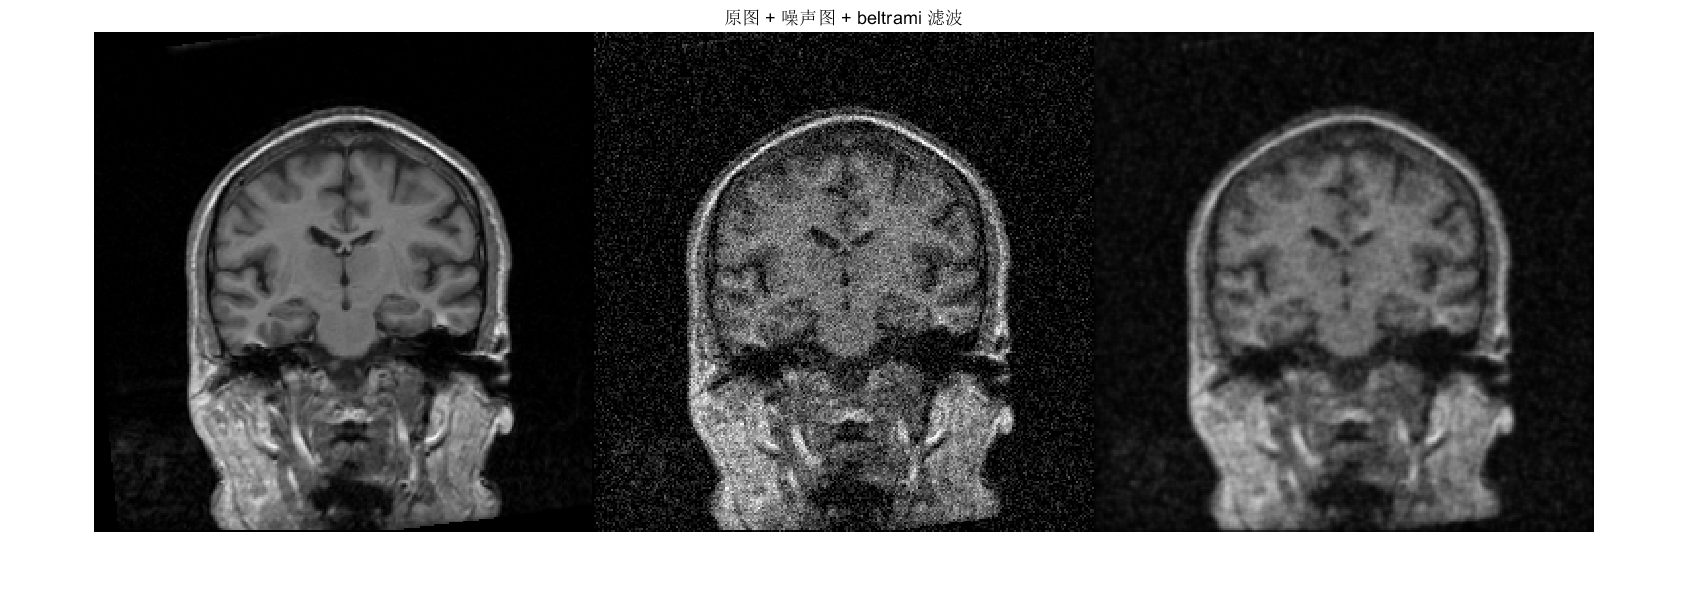

clear;clc;
im = imread('brain.bmp');
if size(im, 3) > 1
    im = rgb2gray(im);
end
rng('default')
im0 = imnoise(im, 'gaussian', 0, 1e-2); % 原图像 + 白噪声
im1 = Beltrami(im0, 30, 0.02);   % beltrami 滤波
montage([im, im0, im1]);
title('原图 + 噪声图 + beltrami 滤波');